close all; 
clear *;
clc;
% Sampling frequency in <Hz>
fs = 1;
% Cutoff frequency in <Hz>
fc = 0.1;
% Filter order
N_7 = 7;
N_15 = 15;
N_31 = 31;
% Design filter (floating-point)
h_7 = fir1(N_7, fc/(fs/2), 'low', hamming(N_7+1));
h_15 = fir1(N_15, fc/(fs/2), 'low', hamming(N_15+1));
h_31 = fir1(N_31, fc/(fs/2), 'low', hamming(N_31+1));


L = 2048;

H_7 = fft(h_7,L);
H_15 = fft(h_15,L);
H_31 = fft(h_31,L);

f = (0:L-1)/L*2;
H_7 = H_7(1:L/2);
H_15 = H_15(1:L/2);
H_31 = H_31(1:L/2);
f = f(1:L/2);




$$$$


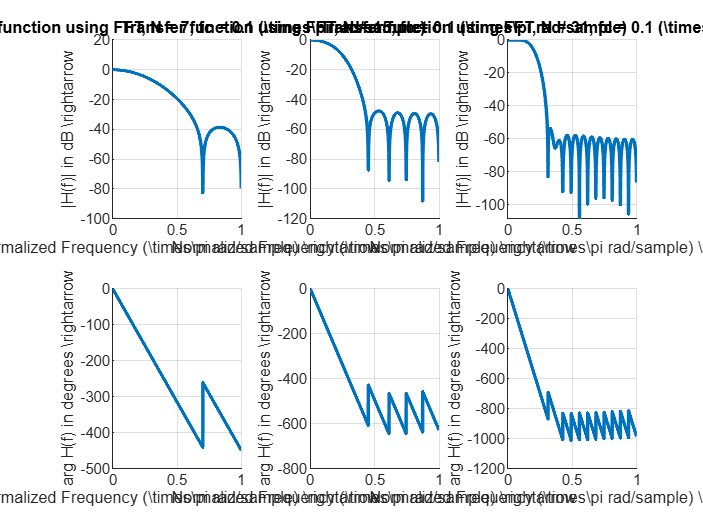

% Plot frequency response (magnitude in dB)
figure(1); % N=7
subplot(2,3,1);
plot(f, 20*log10(abs(H_7)), 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('|H(f)| in dB \rightarrow');
title(['Transfer function using FFT, N = ' num2str(N_7) ', fc = ' num2str(fc) ' (\times\pi rad/sample)']);

% Plot phase response
subplot(2,3,4);
plot(f, unwrap(angle(H_7)) * 180/pi, 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('arg H(f) in degrees \rightarrow');
%N= 15
subplot(2,3,2);
plot(f, 20*log10(abs(H_15)), 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('|H(f)| in dB \rightarrow');
title(['Transfer function using FFT, N = ' num2str(N_15) ', fc = ' num2str(fc) ' (\times\pi rad/sample)']);

% Plot phase response
subplot(2,3,5);
plot(f, unwrap(angle(H_15)) * 180/pi, 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('arg H(f) in degrees \rightarrow');

%N= 31
subplot(2,3,3);
plot(f, 20*log10(abs(H_31)), 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('|H(f)| in dB \rightarrow');
title(['Transfer function using FFT, N = ' num2str(N_31) ', fc = ' num2str(fc) ' (\times\pi rad/sample)']);

% Plot phase response
subplot(2,3,6);
plot(f, unwrap(angle(H_31)) * 180/pi, 'LineWidth', 2); grid on; hold on; box off;
xlabel('Normalized Frequency (\times\pi rad/sample) \rightarrow'); 
ylabel('arg H(f) in degrees \rightarrow');


% Plot impulse response
% figure(2);
% stem(0:N, h, 'LineWidth', 2); hold on; box off;
% xlabel('Coefficient index \rightarrow'); ylabel('Amplitude \rightarrow');
% title('Impulse response');